Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Fitting a straight line with error bars (Section 7.1 and 7.2)

Volker Ziemann, 211118, CC-BY-SA-4.0

In this example we first generate data points scattered around a straight line and subsequently use a linear fit to recover the parameters of the line and the error bars of those parameters.

#### Create data points

Let us first generate data points $y$ that are scattered with $\sigma_y=3$ around $y=as+b=2s-3$, plot the data points, and annotate the axes. Note that $a$ is the slope of the line and $b$ is its intercept.

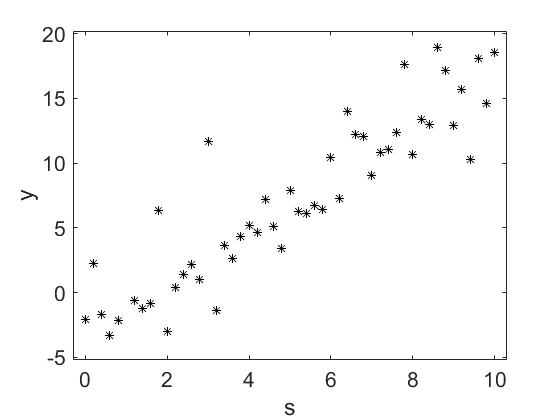

clear
sigy=3;                                % scatter
s=0:0.2:10;
y=2*s-3+sigy*randn(1,length(s));       % straight line with errors
plot(s,y,'k*');                        % data points as black asterisks
xlabel('s'); ylabel('y');              % annotate axes
xlim([-0.3,10.3]); ylim([-5.2,20.2])   % axis limits
set(gca,'FontSize',16)                 % larger fonts

#### Recover the fit parameters from the data points

And now we try to recover the fit parameters $a$ and $b$ from the `N` data points $(s,y)$ by constructing the matrix that appears in Equation 7.1, which relates the slope  $a$ and intercept $b$ to the data points. 

N=length(s);        % number of data points
A=[s',ones(N,1)]    % Matrix in eq. 7.1

A =          0    1.0000
    0.2000    1.0000
    0.4000    1.0000
    0.6000    1.0000
    0.8000    1.0000
    1.0000    1.0000
    1.2000    1.0000
    1.4000    1.0000
    1.6000    1.0000
    1.8000    1.0000


Equation 7.1 is an over-determined linear system that, following the argument in Section 7.2, we can solve in the least-squares sense by calculating the Moore-Penrose pseudo-inverse $(A^tA)^{-1}A^t$ and multiplying it with the column vector of $y$.

x=inv(A'*A)*A'*y'   % pseudo-inverse, eq. 7.4

x =     2.0150
   -3.1435


% x=pinv(A)*y'
% x=polyfit(s,y,1)

Note that Matlab's pinv(A) would also calculate $(A^tA)^{-1}A^t$.  Likewise can we use  `x=polyfit(s,y,1) `to find the fit parameters `x=(a,b)`. We use the found fit parameters in x to generate the regression line with

y_reg=x(1)*s+x(2);

and plot it into the same graph as the data points.

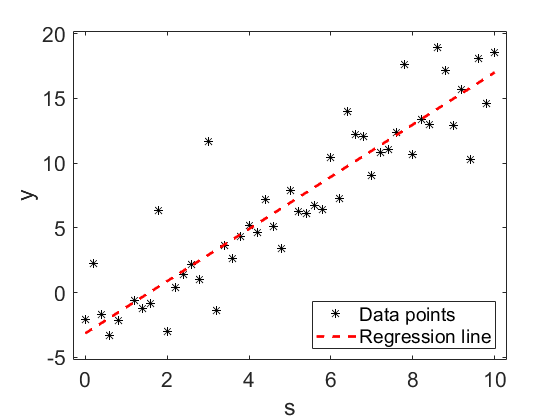

hold on
plot(s,y_reg,'r--','LineWidth',2)
legend('Data points','Regression line','Location','SouthEast')

Running this script multiple times with different random number will produce many different solutions x. We therefore ask ourselves by how much the fit parameters x(1)=a and x(2)=b scatter. In other words, we try to find their error bars.

#### Error bars of the fit parameters

Of course the error bars of the fit parameters depend on the error bars $\sigma_y$ of the $y$. We incorporate them by dividing each row in Equation 7.1 by $\sigma_y$, which, in a slightly more general way is equivalent to Equation 7.3 and that leads to Equation 7.5 to take the error bars of the $y$ into  account. In that equation we need $\Lambda$

Lambda=eye(N)/sigy;

 and find x from Equation 7.5

x=inv(A'*Lambda^2*A)*A'*Lambda^2*y'

x =     2.0150
   -3.1435


which leads to the same value of x as the previously calculated, because in this particular case all the error bars $\sigma_y$ are equal and therefore $\Lambda$ is proportional to the unit matrix. 

But by incorporating $\Lambda$ in the fit we can utilize Equation 7.7 and directly obtain the covariance matrix $C$ of the fit parameters, which contains the error bars on its diagonal.

C=inv(A'*Lambda^2*A)

C =     0.0204   -0.1018
   -0.1018    0.6855


sig_a=sqrt(C(1,1))   % error bar of the slope

sig_a = 0.1427

sig_b=sqrt(C(2,2))   % error bar of the intercept

sig_b = 0.8280

We thus find the result for the slope.

disp(['a = ',num2str(x(1)),' +/- ',num2str(sqrt(C(1,1)))])  % a was 2 

a = 2.015 +/- 0.1427


disp(['b = ',num2str(x(2)),' +/- ',num2str(sqrt(C(2,2)))])  % b was -3

b = -3.1435 +/- 0.82796


We add in passing that the error bars $\sigma_y$ that populate the diagonal of $\Lambda$ do not need to be equal. We just put the error bar $\sigma_y(i)$ of the $i-$th measurement $y(i)$ on the diagonal to account for individual "measurement errors" of the $y(i)$.